# Running DICE

## GAMS results

Load GAMS results for further comparison:

clear

The DICE IAM model is essentially controlled by three variables: $\mu$, $S$, and $\alpha$. Every other variable can be derived or calculated as a function of those three. Hence, there are two ways of solving DICE: solving for these three control variables, or providing one or more of them as a control value. 

As a benchmark, we load the results from previous DICE runs:

load GAMSresults.mat tb paris altdam tb_15 tb_20 disc1

## Optimality Parameters

Before we start solving the problem, we need to define some optimal parameters. These determine how accurate is the solution and how long is going to take to solve the problem.

StepTolerance = 1e-8; % 1e-9 for an accurate (slower solution)
OptimalTolerance = 1e-6; % 1e-7 for an accurate (slower solution)
ConstraintTolerance = 1e-7;

%starting a thread-pool to compute gradients in parallel
if isempty(gcp('nocreate'))
    parpool threads
end

Starting parallel pool (parpool) using the 'threads' profile ...
Connected to parallel pool with 6 workers.


ans =  ThreadPool with properties: 

           NumWorkers: 6
                 Busy: false
            FileStore: [1x1 parallel.FileStore]
           ValueStore: [1x1 parallel.ValueStore]


opts = optimoptions('fmincon',  ...
    'Display', 'off', ...
    "MaxIterations", 999000, ...
    "MaxFunctionEvaluations",999000, ...
    "OptimalityTolerance", OptimalTolerance, ...
    "ConstraintTolerance", ConstraintTolerance, ...
    "StepTolerance", StepTolerance, ...
    "UseParallel", true);

## Solving the Optimized DICE

### Solve

Number of time steps (horizon). Each time step is 5 years

np = 81;

#### **Load the parameters**

params = LoadParams(np);

#### Create the DICE Problem

prob = diceFunc(np, params);

#### Define initial value

x0.MIU = params.miuup(1:np)-eps;
x0.S = 0.25*ones(np, 1);
x0.alpha = [params.a0; 0.4*ones(np-1, 1)];

#### Solve the problem

titer = tic;
[sol,fval,exitflag,output] = solve(prob, x0, Options=opts);
tIteration = toc(titer);

sprintf('Year %d, Iterations = %d, exitFlag = %d, spent = %d secs', ...
    2020 + np*params.tstep, output.iterations,double(exitflag),round(tIteration))

ans = 'Year 2425, Iterations = 167, exitFlag = 2, spent = 26 secs'

### Post process the results

Recover all derived variables such as the Social Cost of Carbon

allVars = recoverAllVars(sol, params);

### Compare the results with GAMS

Note that all results match the GAMS results from the author with a great degree of accuracy except for the social cost of carbon. This is because in GAMS, this value is approximated differently. The official equation[ proposed by the author](https://www.pnas.org/doi/epdf/10.1073/pnas.1609244114) in:


$$SCC(t) = \frac{\partial W}{\partial E(t)}/\frac{\partial W}{\partial C(t)}$$


In GAMS they compute this using the marginal values returned by the program ( `SCC = -1000*eco2eq.m(t)/(.00001+cc.m(t))` ). Here we take a different approach. First the second term is known, we can easily compute that derivative. Second, the first term can be evaluated as follows:

- Add a small perturbation on E(t)

- Compute W

- Calculate the derivative

Then, the easiest way to add a perturbation in E(t) is to add a change in "eland" since it does not affect anything else.

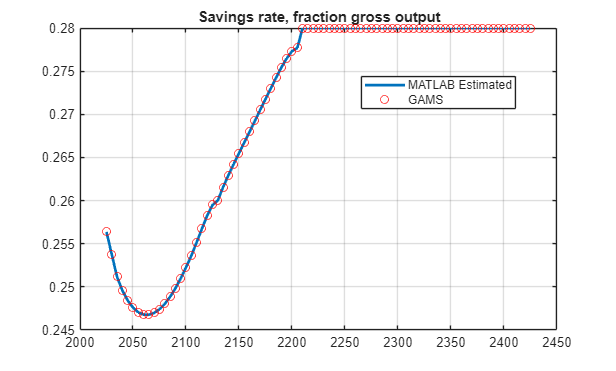

vNames = string(allVars.Properties.VariableNames(1:end-1));
varName = vNames(31);
doPlot(allVars, varName, tb)

## Constraining Temperature

### Tmax = 2.0 Degrees

We can enforce a temperature constraint directly when we create the problem

prob = diceFunc(np, params, TempUpperConstraint=2);

It can be hard to find a solution with a very generic initial condition here. It is easier if we pass the solution from the previous problem.

x0 = sol;

Solve the problem as before

titer = tic;
[sol_20,~,exitflag,output] = solve(prob, x0, Options=opts);
tIteration = toc(titer);

sprintf('Year %d, Iterations = %d, exitFlag = %d, spent = %d secs', ...
    2020 + np*params.tstep, output.iterations,double(exitflag),round(tIteration))

ans = 'Year 2425, Iterations = 115, exitFlag = 2, spent = 21 secs'

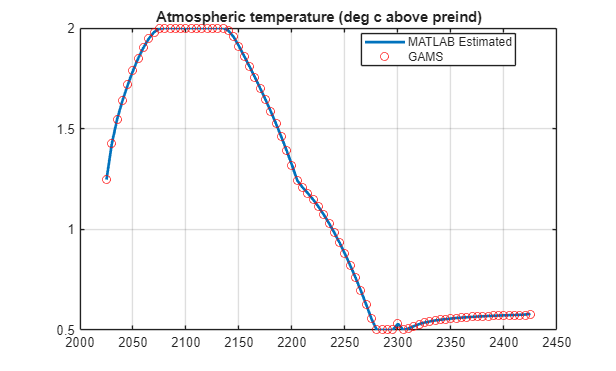

allVars20 = recoverAllVars(sol_20, params);

vNames = string(allVars20.Properties.VariableNames(1:end-1));
varName = vNames(6);
doPlot(allVars20, varName, tb_20)

### Tmax = 1.5 Degrees

At some point, their assumptions break, and for a low temperature constraint the lower limit on S=0 does not hold anymore. In GAMS they seem to have solve this by setting K<= instead of K==. It is easier to unbound S

params = LoadParams(np, SLower=-inf);
prob = diceFunc(np, params, TempUpperConstraint=1.5);

It can be hard to find a solution with a very generic initial condition here. It is easier if we pass the solution from the previous problem.

x0 = sol_20;

Solve the problem as before

titer = tic;
[sol_15,~,exitflag,output] = solve(prob, x0, Options=opts);
tIteration = toc(titer);

sprintf('Year %d, Iterations = %d, exitFlag = %d, spent = %d secs', ...
    2020 + np*params.tstep, output.iterations,double(exitflag),round(tIteration))

ans = 'Year 2425, Iterations = 240, exitFlag = 1, spent = 27 secs'

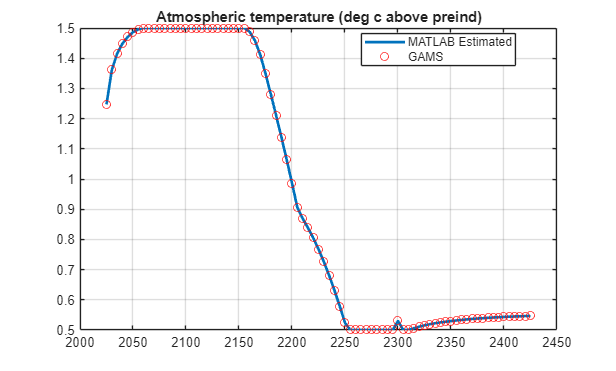

allVars15 = recoverAllVars(sol_15, params);

vNames = string(allVars15.Properties.VariableNames(1:end-1));
varName = vNames(6);
doPlot(allVars15, varName, tb_15)

## Change Parameters

### Override Basic parameters (ALTDAM)

The `LoadParams` function allows overriding any parameter. For example, the ALTDAM option in GAMS

params = LoadParams(a2base = 0.01);
prob = diceFunc(np, params);

x0 = sol;
titer = tic;
[sol_altdam,~,exitflag,output] = solve(prob, x0, Options=opts);
tIteration = toc(titer);

sprintf('Year %d, Iterations = %d, exitFlag = %d, spent = %d secs', ...
    2020 + np*params.tstep, output.iterations,double(exitflag),round(tIteration))

ans = 'Year 2425, Iterations = 136, exitFlag = 2, spent = 21 secs'

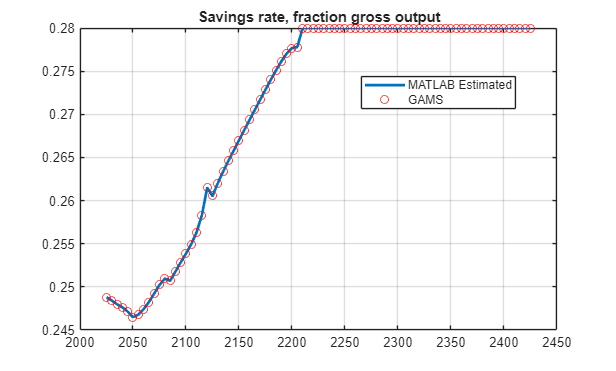

allVarsALTDAM = recoverAllVars(sol_altdam, params);

vNames = string(allVarsALTDAM.Properties.VariableNames(1:end-1));
varName = vNames(31);
doPlot(allVarsALTDAM, varName, altdam)

### Override Limits on MIU (PARIS)

For parameters that cannot be directly overridden, you can always perform the change after. For example:

params = LoadParams(np);

params.miuup(1:5) = min(0.05 + 0.04 * (0:4), 1.00);
params.miuup(6:end) = min(0.05 + 0.04 * (5:np-1) - 0.01 * (1:np-5), 1.00);

prob = diceFunc(np, params);

x0 = sol;
titer = tic;
[sol_paris, ~, exitflag, output] = solve(prob, x0, Options=opts);
tIteration = toc(titer);

sprintf('Year %d, Iterations = %d, exitFlag = %d, spent = %d secs', ...
    2020 + np*params.tstep, output.iterations,double(exitflag),round(tIteration))

ans = 'Year 2425, Iterations = 156, exitFlag = 2, spent = 18 secs'

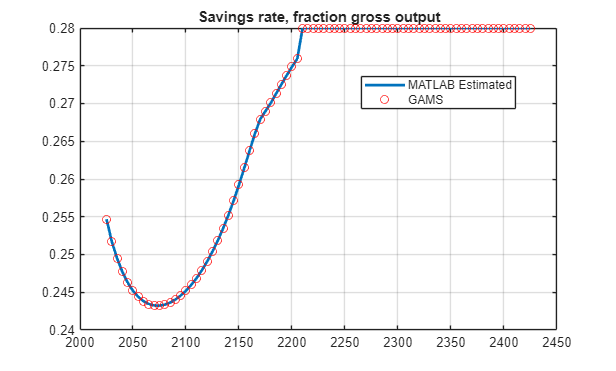

allVarsPARIS = recoverAllVars(sol_paris, params);

vNames = string(allVarsPARIS.Properties.VariableNames(1:end-1));
varName = vNames(31);
doPlot(allVarsPARIS, varName, paris)

### Override multiple (DISCOUT 1%)

params = LoadParams(elasmu = 0.001, prstp = 0.01, k0 = 420);

params.RR1 = 1./((1+params.prstp).^(params.tstep*(0:np-1)));
params.RR = params.RR1';

prob = diceFunc(np, params);

x0 = sol;
titer = tic;
[sol_disc1, ~, exitflag, output] = solve(prob, x0, Options=opts);
tIteration = toc(titer);

sprintf('Year %d, Iterations = %d, exitFlag = %d, spent = %d secs', ...
    2020 + np*params.tstep, output.iterations,double(exitflag),round(tIteration))

ans = 'Year 2425, Iterations = 80, exitFlag = 1, spent = 11 secs'

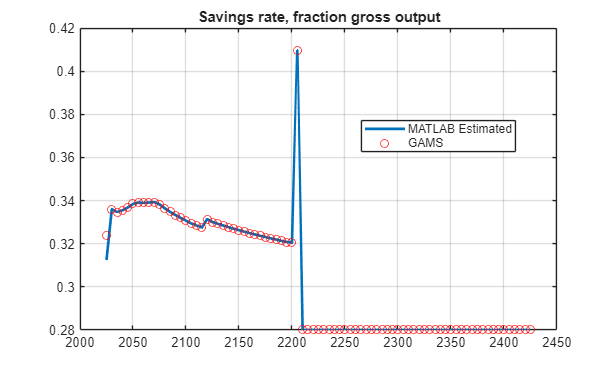

allVarsD1 = recoverAllVars(sol_disc1, params);

vNames = string(allVarsD1.Properties.VariableNames(1:end-1));
varName = vNames(31);
doPlot(allVarsD1, varName, disc1)

## Fix Path for certain variables

It is also possible to fix the path for like MIU, S, or alpha.

### Fix MIU

For example, to fix $\mu$ to one for the entire period. 

MIUFx = ones(np,1);

We would do as follows:

params = LoadParams(a2base = 0.01);
prob = diceFunc(np, params, MIU = MIUFx);

x0 = sol;
titer = tic;
[sol_fx_miu,~,exitflag,output] = solve(prob, x0, Options=opts);
tIteration = toc(titer);

sprintf('Year %d, Iterations = %d, exitFlag = %d, spent = %d secs', ...
    2020 + np*params.tstep, output.iterations,double(exitflag),round(tIteration))

ans = 'Year 2425, Iterations = 82, exitFlag = 2, spent = 10 secs'

You need to add back those values into the solution to postprocess results

sol_fx_miu.MIU = MIUFx;

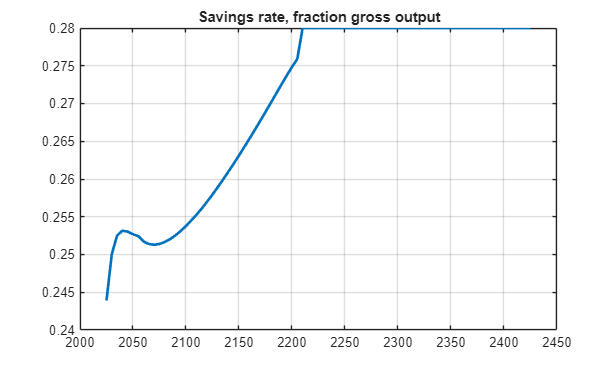

allVarsFX = recoverAllVars(sol_fx_miu, params);
vNames = string(allVarsFX.Properties.VariableNames(1:end-1));
varName = vNames(31);
doPlot(allVarsFX, varName);

function doPlot(allVars, varName, GAMS)

figure
plot(allVars.Year, allVars.(varName), 'LineWidth', 2)
title(varName)
grid on;
if nargin == 3
    hold on;
    plot(allVars.Year, GAMS{varName, :},'ro')
    legend(["MATLAB Estimated", "GAMS"], Location = 'best')
end

end